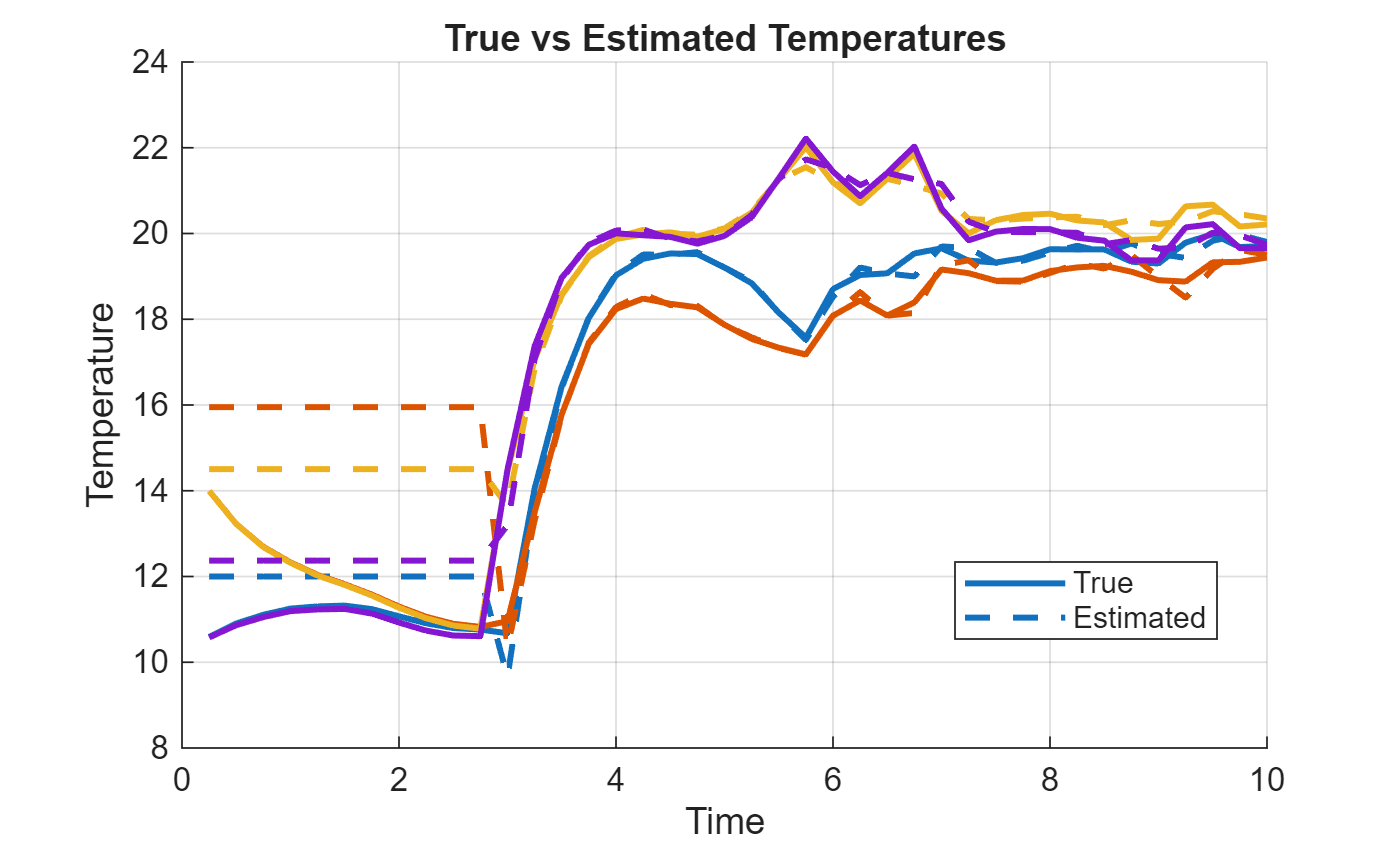

% State estimation
figure; hold on; grid on;

colours = lines(4); % consistent, visually distinct colours

for i = 1:4
    % True (solid)
    plot(t, x(i,2:end), ...
        'Color', colours(i,:), ...
        'LineWidth', 1.8);

    % Estimated (dashed)
    plot(t, x_hat(i,2:end), ...
        '--', ...
        'Color', colours(i,:), ...
        'LineWidth', 1.8);
end

% Minimal legend: style explains meaning
legend({'True', 'Estimated'}, 'Location', 'best');

xlabel('Time');
ylabel('Temperature');
title('True vs Estimated Temperatures');

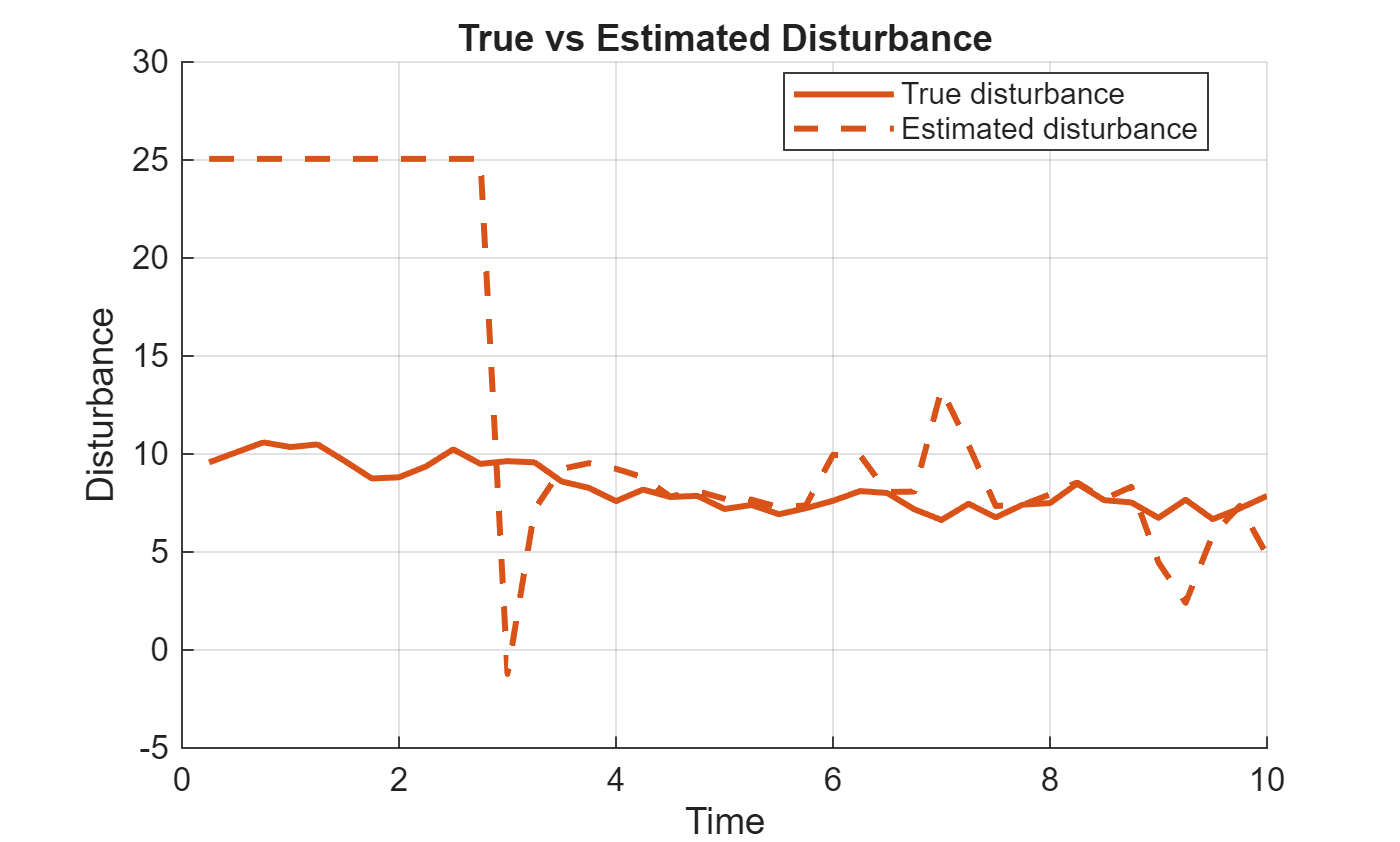


% Disturbance estimation
figure; hold on; grid on;

colour = [0.8500 0.3250 0.0980]; % pick a distinct colour (MATLAB default orange)

% True disturbance (solid)
plot(t, d(2:end), ...
    'Color', colour, ...
    'LineWidth', 1.8);

% Estimated disturbance (dashed)
plot(t, x_hat(5,2:end), ...
    '--', ...
    'Color', colour, ...
    'LineWidth', 1.8);

legend({'True disturbance', 'Estimated disturbance'}, 'Location', 'best');

xlabel('Time');
ylabel('Disturbance');
title('True vs Estimated Disturbance');

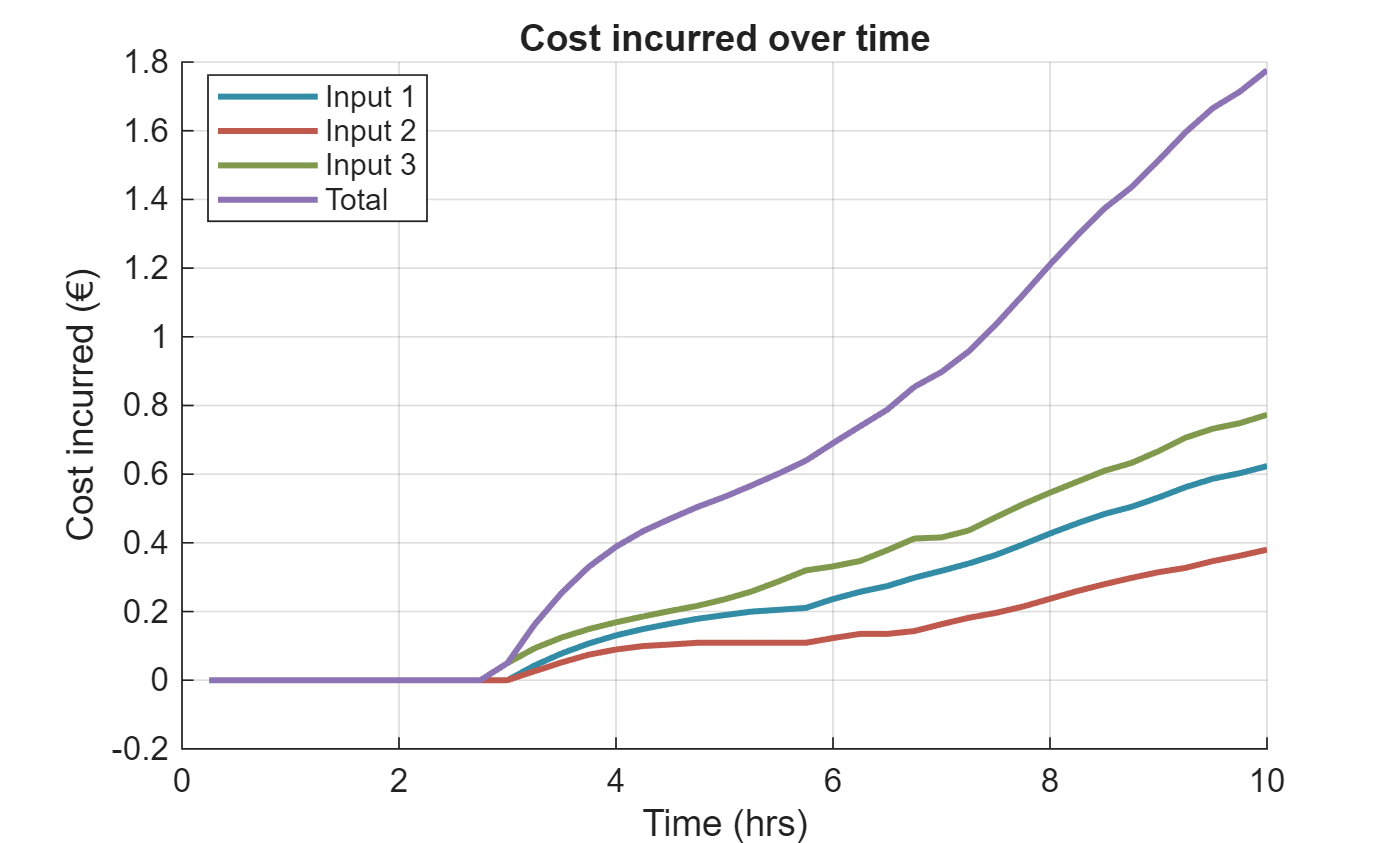


% Total Cost
figure; hold on; grid on;

colour_1 = [0.20 0.55 0.65];
colour_2 = [0.75 0.35 0.30];
colour_3 = [0.50 0.60 0.30];
colour_4 = [0.55 0.45 0.70];

% Input 1
plot(t, cumsum(u(1,:))/100, ...
    'Color', colour_1, ...
    'LineWidth', 1.8);

% Input 2
plot(t, cumsum(u(2,:))/100, ...
    'Color', colour_2, ...
    'LineWidth', 1.8);

% Input 3
plot(t, cumsum(u(3,:))/100, ...
    'Color', colour_3, ...
    'LineWidth', 1.8);

% Input 4
plot(t,cumsum(u(1,:) + u(2,:) + u(3,:))/100, ...
    'Color',colour_4, ...
    'Linewidth', 1.8);

legend({'Input 1', 'Input 2', 'Input 3', 'Total'}, 'Location', 'best');

xlabel('Time (hrs)');
ylabel('Cost incurred (€)');
title('Cost incurred over time');